## Pompe à Chaleur (PAC)

Une pompe à chaleur fonctionne avec le **R 134a** selon le cycle thermodynamique suivant : la vapeur saturée sèche de température $T_1$ = 10.39 °C est comprimée à la pression $p_C$ dans un compresseur à considérer comme adiabatique, avec un rendement isentropique $\eta_{sV}$ = 0.5. Dans le condenseur, la chaleur spécifique $-q_{out}$ est dégagée de manière isobare à une température d'ébullition $T_C$ = 60.45 °C, suivi d'un sous-refroidissement à $T_3$ = 50 °C. Le fluide de travail est ensuite détendu dans une vanne à $p_V$, avant de traverser l'évaporateur où il absorbe, à pression constante, la chaleur spécifique $q_{in}$.

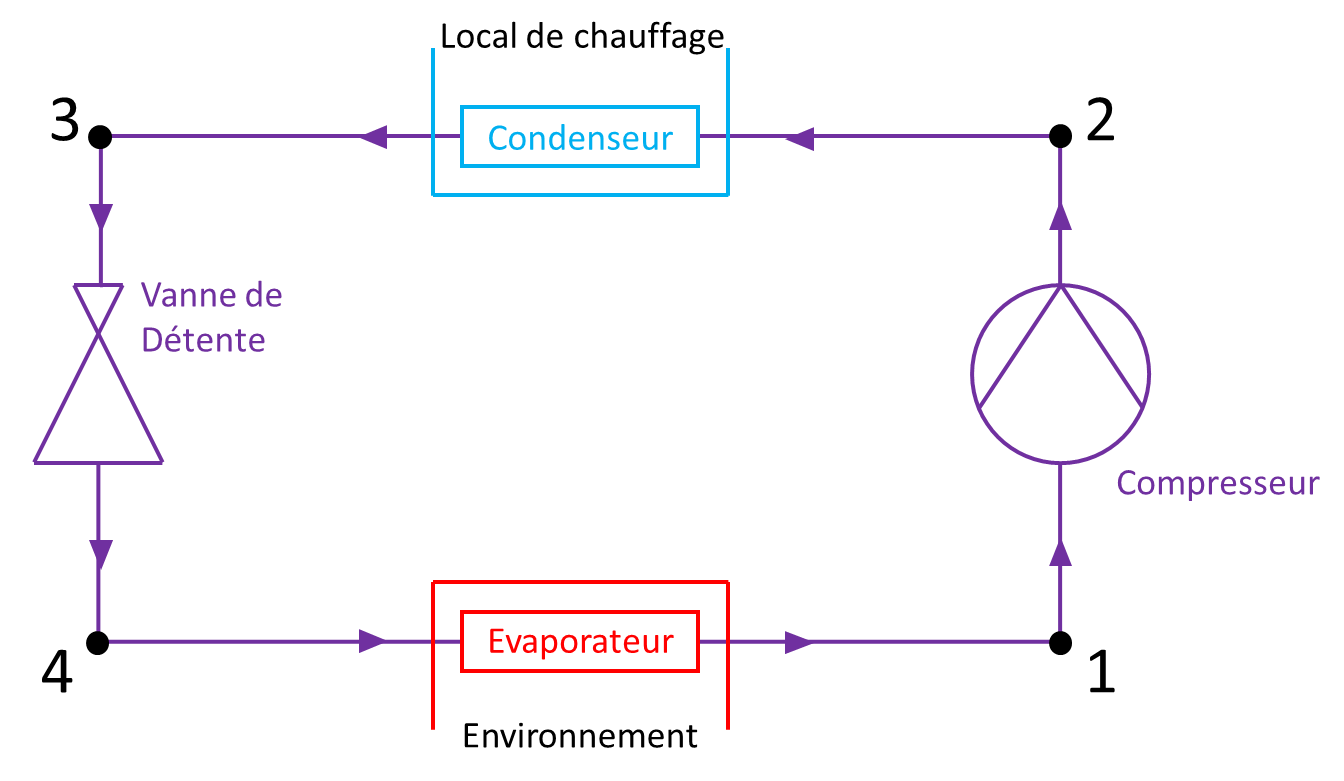

A déterminer :

a) les pressions $p_C$ et $p_V$ et les enthalpies $h_i$ pour tous les états

% état 1
T_1 = 10.39+273.15; x_1 = 1;
p_V = ADVENS_Props('P', 'x', x_1, 'T', T_1, 'R134a')

p_V = 4.1890e+05

h_1 = ADVENS_Props('h', 'x', x_1, 'T', T_1, 'R134a')

h_1 = 4.0737e+05

s_1 = ADVENS_Props('s', 'x', x_1, 'T', T_1, 'R134a')

s_1 = 1.7319e+03


% état 2
eta_sV = 0.5; T_C = 60.45+273.15;
p_C = ADVENS_Props('P', 'x', 1, 'T', T_C, 'R134a')

p_C = 1.7061e+06

h_2s = ADVENS_Props('h', 's', s_1, 'T', T_C, 'R134a')

h_2s = 4.3410e+05

% rappel: eta_sV = (h_2s - h_1) / (h_2 - h_1)
h_2 = h_1 + (h_2s - h_1)/eta_sV

h_2 = 4.6083e+05


s_2 = ADVENS_Props('s', 'h', h_2, 'P', p_C, 'R134a')

s_2 = 1.8001e+03

T_2 = ADVENS_Props('T', 'h', h_2, 'P', p_C, 'R134a')

T_2 = 362.5755



% état 3
T_3 = 50+273.15;
h_3 = ADVENS_Props('h', 'P', p_C, 'T', T_3, 'R134a')

h_3 = 2.7123e+05

s_3 = ADVENS_Props('s', 'P', p_C, 'T', T_3, 'R134a')

s_3 = 1.2347e+03


% état 4
h_4 = h_3

h_4 = 2.7123e+05

p_V

p_V = 4.1890e+05

T_4 = ADVENS_Props('T', 'P', p_V, 'h', h_4, 'R134a')    % what's wrong?

T_4 = 283.5400

%---------------

ADVENS_Props('T', 'P', p_V, 'h', h_4, 'R134a')

ans = 283.5400

Props('T', 'P', p_V/1000, 'H', h_4/1000, 'R134a')

ans = 283.4586


ADVENS_Props('v', 'P', p_V, 'h', h_4, 'R134a')

ans = 0.0154


ADVENS_Props('ThermCond', 'P', p_V, 'h', h_4, 'R134a')

ans = 0.0681

1000*Props('L', 'P', p_V/1000, 'H', h_4/1000, 'R134a')

ans = 0.0180


ADVENS_Props('ThermCond', 'P', p_V, 'v', 0.015366, 'R134a')

ans = 0.0681

1000*Props('L', 'P', p_V/1000, 'D', 1/0.015366, 'R134a')

ans = 0.0177


%---------------

s_4 = ADVENS_Props('s', 'P', p_V, 'h', h_4, 'R134a')

s_4 = 1.2518e+03

b) le tracé approximatif du cycle dans les diagrammes P,h et T,s

Ce cycle est-il parcouru dans le sens horaire ou antihoraire ? Concluez si ce cycle est un consommateur ou un fournisseur de travail. (Justifiez votre réponse.)

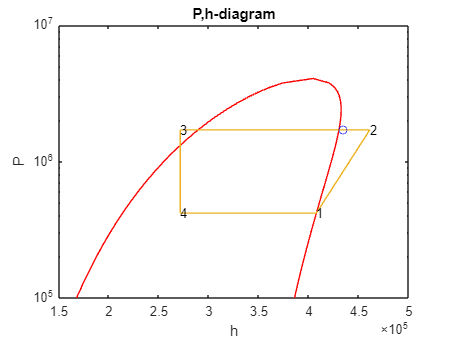

% plot
logPh_diagram('R134a')
hold on;
plot([h_1 h_2 h_3 h_4 h_1], [p_V p_C p_C p_V p_V])
text(h_1, p_V, '1')
text(h_2, p_C, '2')
text(h_3, p_C, '3')
text(h_4, p_V, '4')
hold on;
plot(h_2s, p_C, 'bo')

Ts_diagram('R134a')

hold on;
s_2a = ADVENS_Props('s', 'T', T_C, 'x', 1, 'R134a')

s_2a = 1.7114e+03

s_2b = ADVENS_Props('s', 'T', T_C, 'x', 0, 'R134a')

s_2b = 1.2893e+03

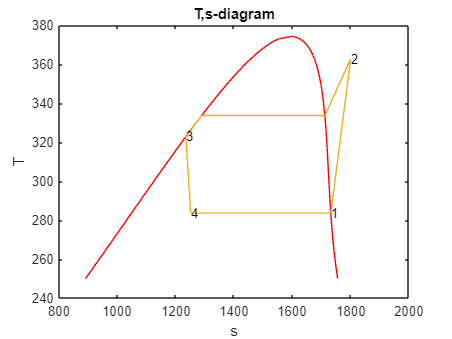

plot([s_1 s_2 s_2a s_2b s_3 s_4 s_1], [T_1 T_2 T_C T_C T_3 T_4 T_1])
text(s_1, T_1, '1')
text(s_2, T_2, '2')
text(s_3, T_3, '3')
text(s_4, T_4, '4')

c) le travail spécifique $w_{tV}$ pour la compression

w_tV = h_2 - h_1

w_tV = 5.3465e+04

d) le débit $\dot{m}$ du fluide frigorigène, si le condenseur émet un $\dot{Q}_{out} = -29 \,\mathrm{kW}$

Q_dot = -29000;
m_dot = Q_dot / (h_3 - h_2)

m_dot = 0.1530

e) la puissance électrique nécessaire $P_{el}$, si le chauffage serait mis en place par chauffage par résistance au lieu d'une pompe à chaleur

P_el = -Q_dot

P_el = 29000

f) le pourcentage de la puissance technique nécessaire pour la PAC vers la puissance électrique du chauffage par résistance

P_tV = m_dot * w_tV

P_tV = 8.1775e+03

percentage = P_tV / P_el

percentage = 0.2820

percentage = -w_tV / (h_3 - h_2)

percentage = 0.2820

g) le coefficient de performance de la pompe à chaleur $COP_{PAC}$

COP_PAC = -Q_dot / P_tV

COP_PAC = 3.5463

COP_PAC = 1/percentage

COP_PAC = 3.5463

h)  le coefficient de qualité $\nu_{PAC}$ en comparaison avec le processus de Carnot équivalent

COP_Carnot = T_C / (T_C - T_1)

COP_Carnot = 6.6640

nu_PAC = COP_PAC / COP_Carnot

nu_PAC = 0.5322